# Preprocesamiento de las imágenes 

close all; clc; clearvars;

Las imágenes están clasificadas en 2 grupos: 

- Sanos 

- Glaucoma 

Etiqueta de calidad con 5 categorías: 

- 0 - Imagen no revisada (se asume correcta, pero podría tener problemas de calidad) 

- 1 - Bajo contraste 

- 2 - Desenfoque 

- 3 - Ruido 

- 4 - Calidad correcta

## Caracteristicas calidad

- Extracción de caracteristicas

- Algoritmo de clasificación para las características extraídas

T_metadata = readtable('metadata.csv');

variables = 1×13 cell array
    {'quality'}    {'entropia'}    {'min_intensidad'}    {'max_intensidad'}    {'rango_dinamico'}    {'std_intensidad'}    {'var_intensidad'}    {'nitidez_borde'}    {'mse'}    {'snr'}    {'score'}    {'magnitud_transformada_promedio'}    {'imagen'}



T_revisada = T_metadata;
T_revisada(T_revisada.quality == 0, :) = [];

### **Distribución categorias**

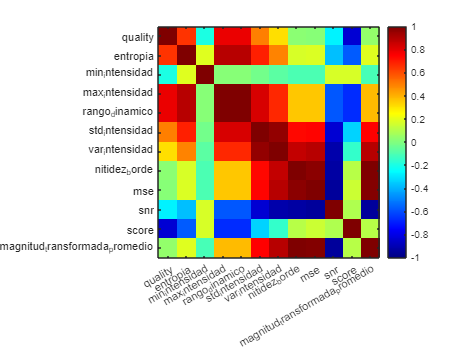

%analisis exploratorio (EDA)
num_bajocontraste = sum(T_revisada.quality == 1);
num_desenfoque = sum(T_revisada.quality == 2);
num_ruido = sum(T_revisada.quality == 3);
num_calidadcorrecta = sum(T_revisada.quality == 4);

num_imagenes_revisadas = [num_bajocontraste, num_desenfoque, num_ruido, num_calidadcorrecta];

bar(1:4, num_imagenes_revisadas);
title('Cantidad de imágenes revisadas de cada categoría de calidad');
xlabel('Categoría de calidad');
ylabel('Número de imágenes');

### Extraer caracteristicas 

- **Rango dinamico: **Diferencia entre el valor máximo y mínimo de los píxeles en una imagen. 

- **Desviación estandar de intensidad:** Indica la variabilidad de los niveles de gris en una imagen

- **Nitidiez del borde: **La nitidez de borde mide la cantidad de cambios abruptos en la intensidad de los píxeles en una imagen, lo que puede indicar la presencia de bordes nítidos y detalles finos.

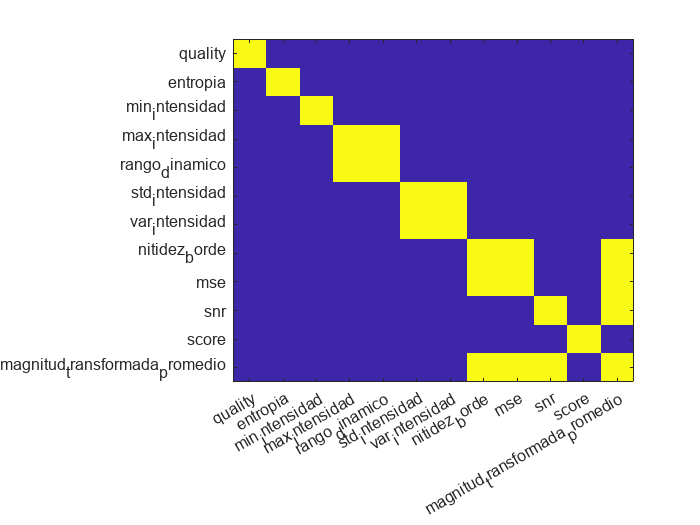

[n, m] = size(T_revisada);

entropia = zeros(n,1);

min_intensidad= zeros(n, 1);
max_intensidad= zeros(n, 1);
rango_dinamico= zeros(n, 1);
std_intensidad= zeros(n, 1);
var_intensidad= zeros(n, 1);
nitidez_borde = zeros(n, 1);
score = zeros(n, 1);
mse = zeros(n, 1);
magnitud_transformada_promedio = zeros(n, 1);
snr = zerons(n,1);
filtro_laplace=[1, 1, 1; 1, -8, 1; 1, 1, 1];

for i = 1:n
    I = imread(T_revisada.image{i});
    entropia(i) = entropy(I);

    I = double(rgb2gray(I)); % damos por hecho que la imagen es de color (igual hacer un for para diferenciar)

    min_intensidad(i)=min(I(:));
    max_intensidad(i)=max(I(:));
    rango_dinamico(i)=max(I(:))-min(I(:));
    std_intensidad(i) = std2(I(:)); % desviación estandar
    var_intensidad(i) =var(I(:)); % varianza

    I2=imfilter(I, filtro_laplace);
    nitidez_borde(i) = sum(abs(I2(:)));

    I_filtrada=medfilt2(I);
    mse(i)=immse(I_filtrada, I);
    snr(i)=psnr(I_filtrada, I);
    score(i) = brisque(I);

    transformada = fft2(I);
    magnitud_transformada = abs(transformada);
    magnitud_transformada_promedio(i) = mean(magnitud_transformada(:));
end

T_caracteristicas = table(T_revisada.quality, entropia, min_intensidad, max_intensidad, rango_dinamico, std_intensidad, var_intensidad, nitidez_borde, mse, snr, score, magnitud_transformada_promedio, 'VariableNames', {'quality', 'entropia', 'min_intensidad', 'max_intensidad', 'rango_dinamico', 'std_intensidad', 'var_intensidad', 'nitidez_borde', 'mse', 'snr', 'score', 'magnitud_transformada_promedio'});
T_caracteristicas.imagen = T_revisada.image;

### Save table 

writetable(T_caracteristicas, 'CaracteristicasCalidadREVISADAS_TODAS.csv');

## Desarrollo modelo

### 1. Load data

T = readtable("CaracteristicasCalidadREVISADAS_TODAS2.csv");

#### Correlation

variables=T.Properties.VariableNames
X = T{:, 1:end-1};
R = corrcoef(X, 'Rows', 'pairwise'); % pairwise to ignore NaN values

figure;
imagesc(R); clim([-1 1]);
xticks(1:30);
xticklabels(variables(:));
yticks(1:30);
yticklabels(variables(:));
colormap(jet); colorbar;

figure;
imagesc(abs(R)>0.95); clim([0 1]);
xticks(1:30);
xticklabels(variables(:));

yticks(1:30);
yticklabels(variables(:));

#### Preprocessing

T.imagen=[];
T.min_intensidad=[];
T.max_intensidad=[];
T.magnitud_transformada_promedio=[];
T.mse=[];
T.nitidez_borde=[];
T.var_intensidad=[];
T.score=[];

% caracteristicas para el modelo: entropia, rango_dinamico, std_intensidad, snr

[n, ~]=size(T);

T.quality = cellstr(num2str(T.quality)); %convertir quality en variable categorica
for i = 1:n
    if T.quality{i} == '1'
        T.quality{i} = 'Bajo Contraste';
    elseif T.quality{i} == '2'
        T.quality{i} = 'Desenfoque';
    elseif T.quality{i} == '3'
        T.quality{i} = 'Ruido';
    elseif T.quality{i} == '4'
        T.quality{i} = 'Calidad Correcta';
    end
end

### 2. Data split

rng(4); 
p = 0.2;
cv_out = cvpartition(T.quality, 'HoldOut', p, 'Stratify', true); 
% 20% -> pruebas

results = 6×3 table
        model          loss       accuracy
    _____________    _________    ________

    "knn"              0.03629    0.96371 
    "tree"            0.016129    0.98387 
    "naive_bayes"    0.0044843    0.94355 
    "LDA"            0.0080645    0.99194 
    "QDA"             0.020161    0.97984 
    "SVM"            0.0040323    0.99597 


% 80% -> entrenar el modelo. 
% 'Stratify', true asegura que la distribución de clases se mantenga tanto en los conjuntos de entrenamiento como en los de prueba

ans = 1×3 table
    model      loss       accuracy
    _____    _________    ________

    "SVM"    0.0040323    0.99597 



T_train = T(cv_out.training, :); 
T_test  = T(cv_out.test, :);

k = 10; % técnica de validación cruzada de 10 pliegues
cv_in = cvpartition(T_train.quality, 'KFold', k, 'Stratify', true);

loss_final = 0.0489

### **3. Model training**

results = table;

#### **K-nearest neighbors (KNN)**

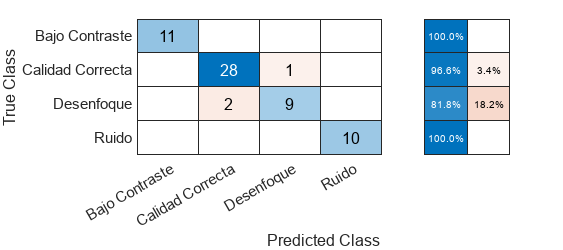

mdl_knn = fitcknn(T_train, 'quality', 'NumNeighbors', 3, 'CVPartition', cv_in); % number of neighbors: 3
mdl_loss = kfoldLoss(mdl_knn); % mean error value

Y_pred = kfoldPredict(mdl_knn);


accuracy = sum(strcmp(Y_pred, T_train.quality)) / height(T_train);
results = [results; table("knn", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

#### **Classification Trees**

mdl_tree = fitctree(T_train, 'quality', 'CVPartition', cv_in);
mdl_loss = kfoldLoss(mdl_tree);

Y_pred = kfoldPredict(mdl_tree);

loss_final2 = 0.0161


accuracy = sum(strcmp(T_train.quality, Y_pred)) / height(T_train);
results = [results; table("tree", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

#### Naive Bayes

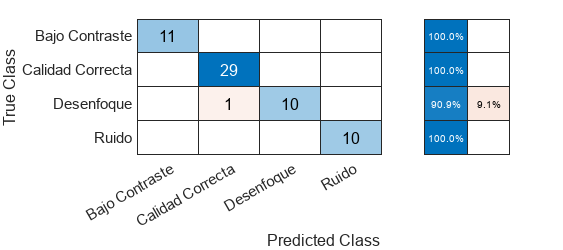

mdl_NB = fitcnb(T_train, 'quality','CVPartition', cv_in);
mdl_loss = kfoldLoss(mdl_NB);


Y_pred = kfoldPredict(mdl_NB);

accuracy = sum(strcmp(Y_pred, T_train.quality)) / height(T_train);
results = [results; table("naive_bayes", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

#### Discriminant Analysis

- **LDA**: asume que las matrices de covarianza de cada clase son iguales.

mdl_lda = fitcdiscr(T_train, 'quality','CVPartition', cv_in);

loss_final3 = 0

mdl_loss = kfoldLoss(mdl_lda);
Y_pred = kfoldPredict(mdl_lda);
accuracy = sum(strcmp(Y_pred, T_train.quality)) / height(T_train);

results = [results; table("LDA", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

- **QDA:** asume que las matrices de covarianza de cada clase son diferentes.

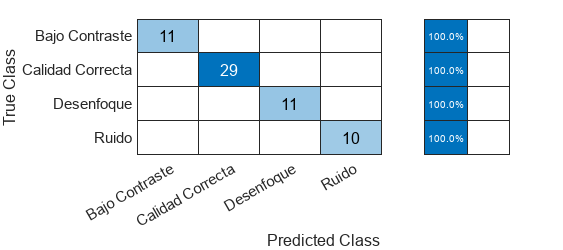

mdl_qda = fitcdiscr(T_train, 'quality','DiscrimType','quadratic','CVPartition',cv_in);

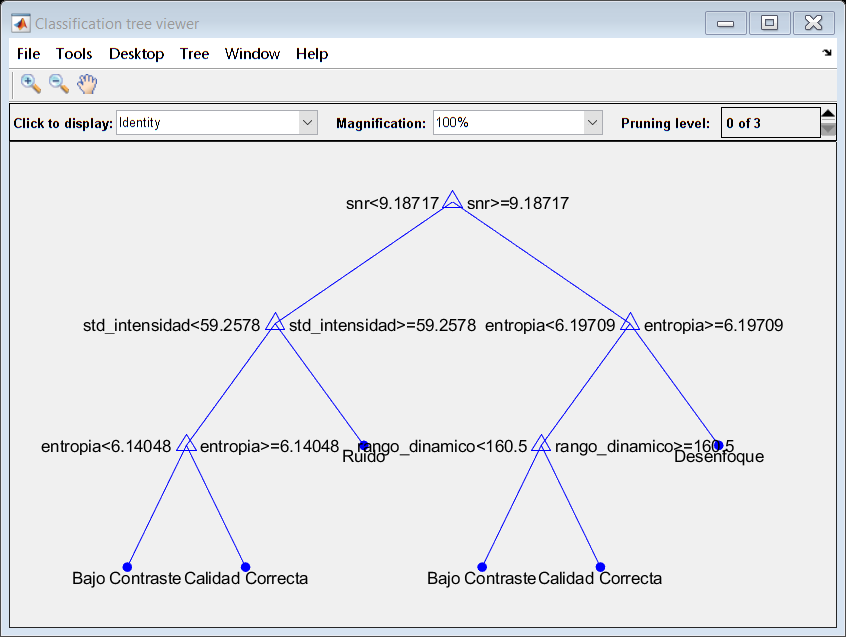

mdl_loss = kfoldLoss(mdl_qda);

Y_pred = kfoldPredict(mdl_qda);


accuracy = sum(strcmp(Y_pred, T_train.quality)) / height(T_train);
results = [results; table("QDA", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

#### **Support Vector Machines (SVM)**

mdl_svm = fitcecoc(T_train, 'quality','CVPartition',cv_in);
mdl_loss = kfoldLoss(mdl_svm);

Y_pred = kfoldPredict(mdl_svm);

accuracy = sum(strcmp(Y_pred, T_train.quality)) / height(T_train);
results = [results; table("SVM", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

### 4. Model comparison

results
[~, best_model] = min(results.loss);
results(best_model, :)

### 5. Final model testing

#### **Discriminant Analysis**

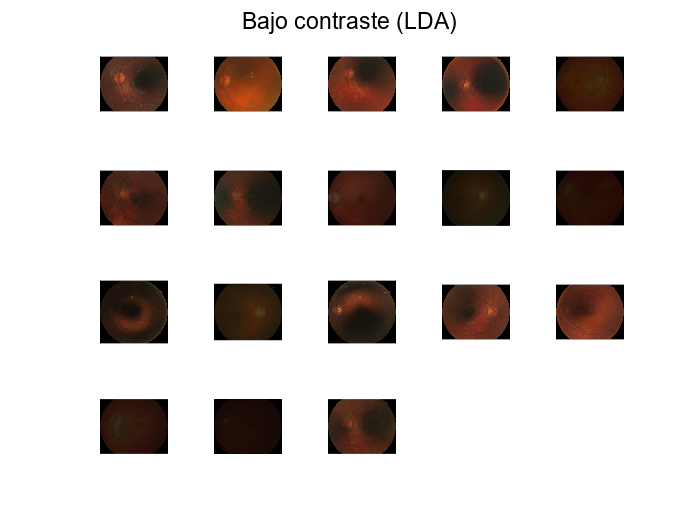

mdl_final_LDA = fitcdiscr(T_train, 'quality');
Y_pred = predict(mdl_final_LDA, T_test);

loss_final = loss(mdl_final_LDA, T_test)
accuracy_final = sum(strcmp(Y_pred, T_test.quality)) / height(T_test.quality);

Y_test  = T.quality(cv_out.test);


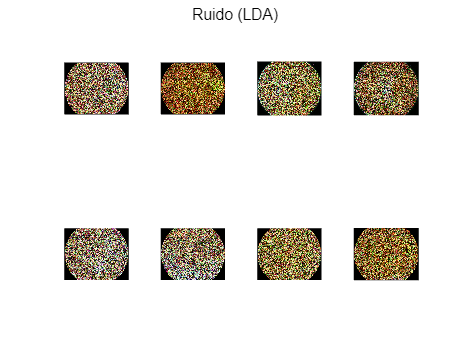

figure('Position', [0 0 450 200]);
confusionchart(Y_test, Y_pred, 'RowSummary','row-normalized')

mdl_final_TODO_LDA = fitcdiscr(T, 'quality');

#### **Support Vector Machines (SVM)**

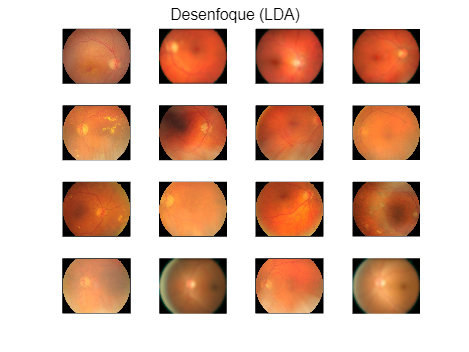

mdl_final_SVM = fitcnb(T_train, 'quality');
Y_pred2 = predict(mdl_final_SVM, T_test);

loss_final2 = loss(mdl_final_SVM, T_test)

accuracy_final2 = sum(strcmp(Y_pred2, T_test.quality)) / height(T_test.quality);

Y_test  = T.quality(cv_out.test);

figure('Position', [0 0 450 200]);
confusionchart(Y_test, Y_pred2, 'RowSummary','row-normalized')

mdl_final_TODO_SVM = fitcecoc(T, 'quality');

#### Classification trees

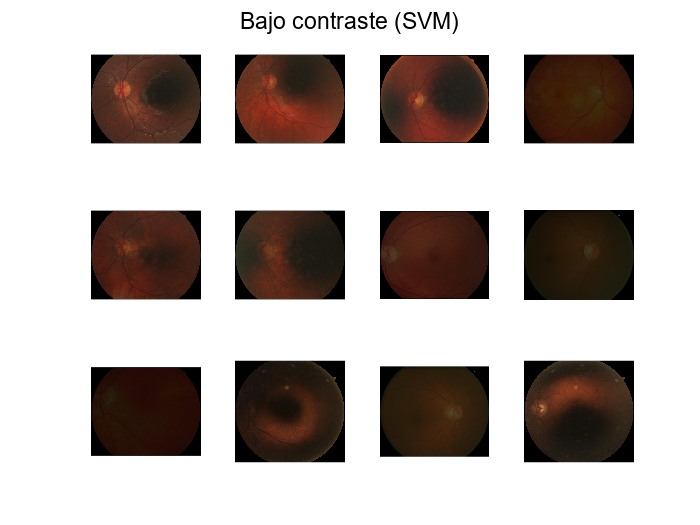

mdl_final_TREE = fitctree(T_train, 'quality');
Y_pred3 = predict(mdl_final_TREE, T_test);

loss_final3 = loss(mdl_final_TREE, T_test)

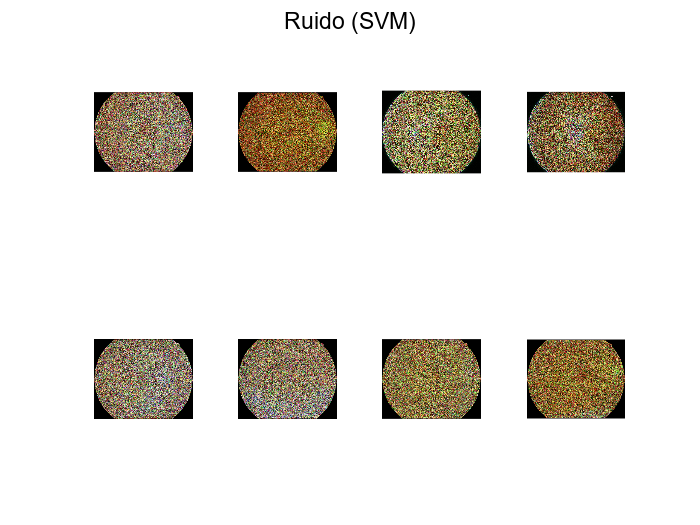

accuracy_final3 = sum(strcmp(Y_pred3, T_test.quality)) / height(T_test.quality);

Y_test  = T.quality(cv_out.test);

figure('Position', [0 0 450 200]);

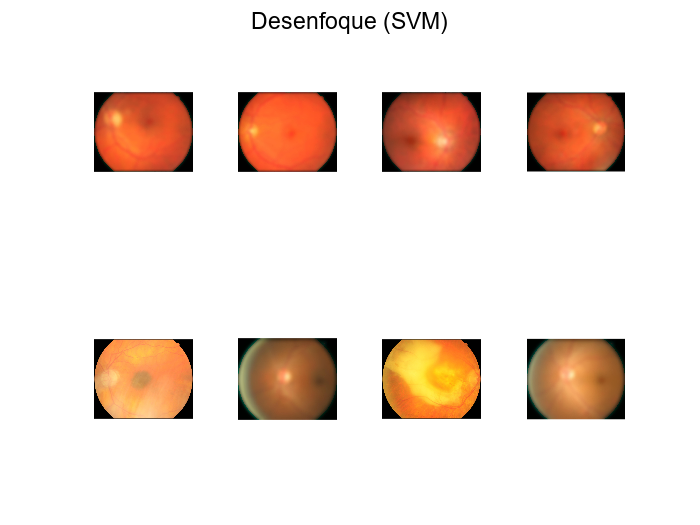

confusionchart(Y_test, Y_pred3, 'RowSummary','row-normalized')

mdl_final_TODO_TREE = fitctree(T, 'quality');
view(mdl_final_TODO_TREE, 'Mode','graph')

## Caracteristicas de imagenes no revisadas

no_revisadas = T_metadata.image(T_metadata.quality == 0);

### Extraer caracteristicas 

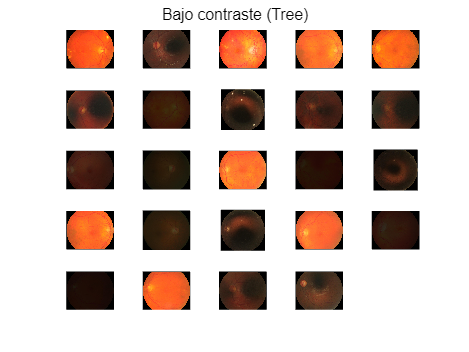

[n, m] = size(no_revisadas);

entropia2 = zeros(n,1);
min_intensidad2= zeros(n, 1);
max_intensidad2= zeros(n, 1);
rango_dinamico2= zeros(n, 1);
std_intensidad2= zeros(n, 1);
var_intensidad2= zeros(n, 1);
nitidez_borde2 = zeros(n, 1);
score2 = zeros(n, 1);

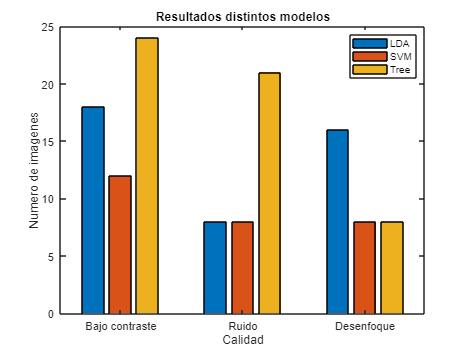

mse2 = zeros(n, 1);
magnitud_transformada_promedio2 = zeros(n, 1);
snr2 = zeros(n,1);

filtro_laplace=[1, 1, 1; 1, -8, 1; 1, 1, 1];

for i = 1:n
    I = imread(no_revisadas{i});
    entropia2(i) = entropy(I);

    I = double(rgb2gray(I)); % damos por hecho que la imagen es de color (igual hacer un for para diferenciar)

    min_intensidad2(i)=min(I(:));
    max_intensidad2(i)=max(I(:));
    rango_dinamico2(i)=max(I(:))-min(I(:));

    std_intensidad2(i) = std2(I(:)); % desviación estandar
    var_intensidad2(i) =var(I(:)); % varianza

    I2=imfilter(I, filtro_laplace);
    nitidez_borde2(i) = sum(abs(I2(:)));

    I_filtrada=medfilt2(I);
    mse2(i)=immse(I_filtrada, I);
    snr2(i)=psnr(I_filtrada, I);

    score2(i) = brisque(I);

    transformada = fft2(I);
    magnitud_transformada = abs(transformada);
    magnitud_transformada_promedio2(i) = mean(magnitud_transformada(:));
end

T_caracteristicas_norevisadas = table(entropia2, min_intensidad2, max_intensidad2, rango_dinamico2, std_intensidad2, var_intensidad2, nitidez_borde2, mse2, snr2, score2, magnitud_transformada_promedio2, 'VariableNames', {'entropia', 'min_intensidad', 'max_intensidad', 'rango_dinamico', 'std_intensidad', 'var_intensidad', 'nitidez_borde', 'mse', 'snr', 'score', 'magnitud_transformada_promedio'});
variables=T_caracteristicas.Properties.VariableNames;
% 
% T_caracteristicas_norevisadas.imagen = no_revisadas.image;

### Save table 

writetable(T_caracteristicas_norevisadas, 'CaracteristicasCalidadNOREVISADAS_TODAS.csv');

## Predicción

T_metadata = readtable('metadata.csv');
no_revisadas = T_metadata.image(T_metadata.quality == 0);
T_caracteristicas_norevisadas = readtable("CaracteristicasCalidadNOREVISADAS_TODAS2.csv");

% prediccion = predict(mdl_final, T_caracteristicas_norevisadas);
% T_calidad = table(no_revisadas, prediccion, 'VariableNames', {'Imagen', 'Calidad'})
% Bajo_contraste = T_calidad.Imagen(strcmp(T_calidad.Calidad, 'Bajo Contraste'))
% Ruido = T_calidad.Imagen(strcmp(T_calidad.Calidad, 'Ruido'))
% Desenfoque = T_calidad.Imagen(strcmp(T_calidad.Calidad, 'Desenfoque'))
% Calidad_correcta = T_calidad.Imagen(strcmp(T_calidad.Calidad, 'Calidad Correcta'))
% 
% prediccion2 = predict(mdl_final2, T_caracteristicas_norevisadas);
% T_calidad2 = table(no_revisadas, prediccion2, 'VariableNames', {'Imagen', 'Calidad'})
% Bajo_contraste2 = T_calidad2.Imagen(strcmp(T_calidad2.Calidad, 'Bajo Contraste'))
% Calidad_correcta2 = T_calidad2.Imagen(strcmp(T_calidad2.Calidad, 'Calidad Correcta'))
% Ruido2 = T_calidad2.Imagen(strcmp(T_calidad2.Calidad, 'Ruido'))
% Desenfoque2 = T_calidad2.Imagen(strcmp(T_calidad2.Calidad, 'Desenfoque'))

#### **Discriminant Analysis**

prediccion3 = predict(mdl_final_TODO_LDA, T_caracteristicas_norevisadas);
T_calidad3 = table(no_revisadas, prediccion3, 'VariableNames', {'Imagen', 'Calidad'});
Bajo_contraste_LDA = T_calidad3.Imagen(strcmp(T_calidad3.Calidad, 'Bajo Contraste'));
Calidad_correcta_LDA = T_calidad3.Imagen(strcmp(T_calidad3.Calidad, 'Calidad Correcta'));
Ruido_LDA = T_calidad3.Imagen(strcmp(T_calidad3.Calidad, 'Ruido'));
Desenfoque_LDA = T_calidad3.Imagen(strcmp(T_calidad3.Calidad, 'Desenfoque'));

figure; sgtitle('Bajo contraste (LDA)')
for i=1:18
   subplot(4,5,i); imshow(Bajo_contraste_LDA{i});
end

figure; sgtitle('Ruido (LDA)')
for i=1:8
   subplot(2,4,i); imshow(Ruido_LDA{i});
end

figure; sgtitle('Desenfoque (LDA)')
for i=1:16
   subplot(4,4,i); imshow(Desenfoque_LDA{i});
end

#### **Support Vector Machines (SVM)**

prediccion4 = predict(mdl_final_TODO_SVM, T_caracteristicas_norevisadas);
T_calidad4 = table(no_revisadas, prediccion4, 'VariableNames', {'Imagen', 'Calidad'});
Bajo_contraste_SVM = T_calidad4.Imagen(strcmp(T_calidad4.Calidad, 'Bajo Contraste'));
Calidad_correcta_SVM = T_calidad4.Imagen(strcmp(T_calidad4.Calidad, 'Calidad Correcta'));
Ruido_SVM = T_calidad4.Imagen(strcmp(T_calidad4.Calidad, 'Ruido'));
Desenfoque_SVM = T_calidad4.Imagen(strcmp(T_calidad4.Calidad, 'Desenfoque'));

figure; sgtitle('Bajo contraste (SVM)')
for i=1:12
   subplot(3,4,i); imshow(Bajo_contraste_SVM{i});
end

figure; sgtitle('Ruido (SVM)')
for i=1:8
   subplot(2,4,i); imshow(Ruido_SVM{i});
end

figure; sgtitle('Desenfoque (SVM)')
for i=1:8
   subplot(2,4,i); imshow(Desenfoque_SVM{i});
end

#### **Classification Tree**

prediccion5 = predict(mdl_final_TODO_TREE, T_caracteristicas_norevisadas);
T_calidad5 = table(no_revisadas, prediccion5, 'VariableNames', {'Imagen', 'Calidad'});
Bajo_contraste_TREE = T_calidad5.Imagen(strcmp(T_calidad5.Calidad, 'Bajo Contraste'));
Calidad_correcta_TREE = T_calidad5.Imagen(strcmp(T_calidad5.Calidad, 'Calidad Correcta'));
Ruido_TREE = T_calidad5.Imagen(strcmp(T_calidad5.Calidad, 'Ruido'));
Desenfoque_TREE = T_calidad5.Imagen(strcmp(T_calidad5.Calidad, 'Desenfoque'));

figure; sgtitle('Bajo contraste (Tree)')
for i=1:24
   subplot(5,5,i); imshow(Bajo_contraste_TREE{i});
end

figure; sgtitle('Ruido (Tree)')
for i=1:21
   subplot(5,5,i); imshow(Ruido_TREE{i});
end

figure; sgtitle('Desenfoque (Tree)')
for i=1:8
   subplot(2,4,i); imshow(Desenfoque_TREE{i});
end

Comp = [length(Bajo_contraste_LDA), length(Bajo_contraste_SVM), length(Bajo_contraste_TREE); length(Ruido_LDA), length(Ruido_SVM), length(Ruido_TREE); length(Desenfoque_LDA), length(Desenfoque_SVM), length(Desenfoque_TREE)];
figure; bar(Comp); legend('LDA', 'SVM', 'Tree')
xticklabels({'Bajo contraste', 'Ruido', 'Desenfoque'})
title('Resultados distintos modelos'); xlabel('Calidad'); ylabel('Numero de imagenes')

## Imagenes calidad correcta

T_metadata = readtable('metadata.csv');
I_calidadcorrecta = [T_metadata.image(T_metadata.quality == 4, :); Calidad_correcta_LDA];

T_calidadcorrecta = T_metadata(ismember(T_metadata.image, I_calidadcorrecta), :);

writetable(T_calidadcorrecta, 'metadataCALIDADCORRECTA.csv');